**Initial data exploration**

Load the file and check its size

% add spreadsheet folder to path
filepath = '/home/ori/catkin_ws/src/multi_sensor_tracker/results_CSVs';
addpath(filepath)

res_filename = "res_0318_151.csv";
res_table = readtable(res_filename);
fprintf('res_table has size (%d,%d)',size(res_table,1),size(res_table,2))

res_table has size (1992,12)

res_table(1:3,:) %print the first few rows

ans = 3×12 table
     Time      isRGBD    Detection_X    Detection_Y    Detection_Z    Tracklet_ID     KF_X        KF_Y           KF_Z        KF_cov_X    KF_cov_Y    KF_cov_Z
    _______    ______    ___________    ___________    ___________    ___________    ______    ___________    ___________    ________    ________    ________

    0.30386    1         8.2587         7.4337e+251    4.0701e+266    2              8.2554    6.1449e+251    7.8353e+265    3.4674      3.4674      0.80749 
    0.33745    1         8.2555         9.8943e+251    2.9085e+266    2              8.2508    8.468

gnd_filename = "gnd_0318_151.csv";
gnd_table = readtable(gnd_filename);
fprintf('gnd_table has size (%d,%d)',size(gnd_table,1),size(gnd_table,2))

gnd_table has size (2755,5)

gnd_table(1:3,:) %print the first few rows

ans = 3×5 table
     Time      isRGBD    Detection_X    Detection_Y    Detection_Z
    _______    ______    ___________    ___________    ___________

          0    0         2.6639          1.5947        1.6871     
          0    0         3.8002         0.82254        1.7704     
    0.10085    0         2.6583          1.6128        1.6487     


Plot the detection values

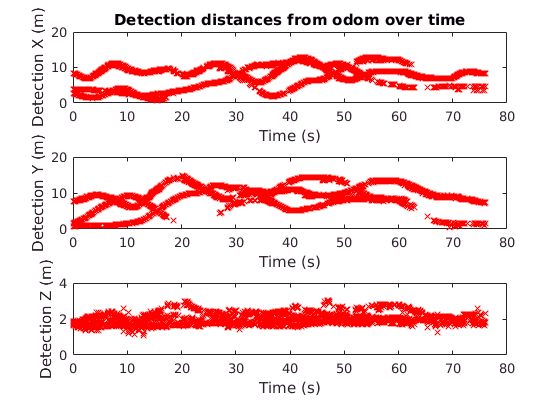

figure
subplot(3,1,1)
plot(gnd_table.Time, gnd_table.Detection_X, 'rx')
title('Detection distances from odom over time')

xlabel('Time (s)')
ylabel('Detection X (m)')
subplot(3,1,2)
plot(gnd_table.Time, gnd_table.Detection_Y, 'rx')
xlabel('Time (s)')
ylabel('Detection Y (m)')
subplot(3,1,3)
plot(gnd_table.Time, gnd_table.Detection_Z, 'rx')
xlabel('Time (s)')
ylabel('Detection Z (m)')

Ok so it seems difficult to distinguish between different detections. Clearly there are patterns in X,Y and Z is predictably noisy. Could filter results by detection type (RGB or LIDAR).

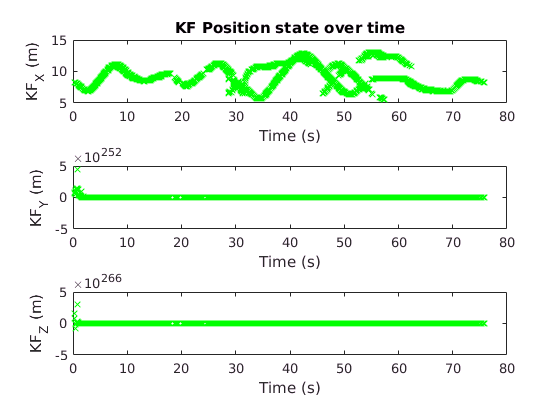

figure
subplot(3,1,1)
plot(res_table.Time, res_table.KF_X, 'gx')
title('KF Position state over time')

xlabel('Time (s)')
ylabel('KF_X (m)')
subplot(3,1,2)
plot(res_table.Time, res_table.KF_Y, 'gx')
xlabel('Time (s)')
ylabel('KF_Y (m)')
subplot(3,1,3)
plot(res_table.Time, res_table.KF_Z, 'gx')
xlabel('Time (s)')
ylabel('KF_Z (m)')

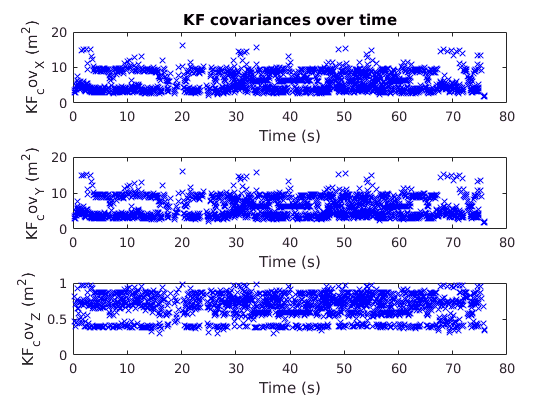

figure
subplot(3,1,1)
plot(res_table.Time, res_table.KF_cov_X, 'bx')
title('KF covariances over time')

xlabel('Time (s)')
ylabel('KF_cov_X (m^2)')
subplot(3,1,2)
plot(res_table.Time, res_table.KF_cov_Y, 'bx')
xlabel('Time (s)')
ylabel('KF_cov_Y (m^2)')
subplot(3,1,3)
plot(res_table.Time, res_table.KF_cov_Z, 'bx')
xlabel('Time (s)')
ylabel('KF_cov_Z (m^2)')

Now let's split into tracklets and superimpose the tracklet paths

% Tracklet_table = T(T.Tracklet_ID == 0,:)
max_tracklet_id = max(res_table.Tracklet_ID);
tracklet_table_array = cell(1,2);
cell_length = 1;

for i = 1:max_tracklet_id
    tracklet_table = res_table(res_table.Tracklet_ID == i,:);
    if size(tracklet_table,1 > 0) % if this table contains data, add it to the cell array
        tracklet_table_array(cell_length,:) = {i,tracklet_table};
        cell_length = cell_length + 1; %counter for cell array
        fprintf('adding table with id %d to trackle_table_array\n',i)
    end
end

adding table with id 2 to trackle_table_array


adding table with id 3 to trackle_table_array


adding table with id 4 to trackle_table_array


adding table with id 9 to trackle_table_array


adding table with id 12 to trackle_table_array


adding table with id 13 to trackle_table_array


adding table with id 17 to trackle_table_array


adding table with id 18 to trackle_table_array


adding table with id 20 to trackle_table_array


%check that this has generated correctly
% for i=1:size(tracklet_table_array)
%     tracklet_table_array{i,2}(:,:)
% end
tracklet_table_array{1,2}(:,:)

ans = 790×12 table
     Time      isRGBD    Detection_X    Detection_Y     Detection_Z     Tracklet_ID     KF_X         KF_Y            KF_Z        KF_cov_X    KF_cov_Y    KF_cov_Z
    _______    ______    ___________    ____________    ____________    ___________    ______    ____________    ____________    ________    ________    ________

    0.30386    1              8.2587     7.4337e+251     4.0701e+266    2              8.2554     6.1449e+251     7.8353e+265    3.4674      3.4674      0.80749 
    0.33745    1              8.2555     9.8943e+251     2.9085e+266    2             

Now we want to see how this compares to the detections. Let's superimpose the detection values

figure
subplot(2,1,1)
plot(gnd_table.Time,gnd_table.Detection_X,'k.','LineWidth',1)

subplot(2,1,2)
plot(gnd_table.Time,gnd_table.Detection_Y,'k.','LineWidth',1)

Now we've split the table into tracklets, let's plot some of their trajectories

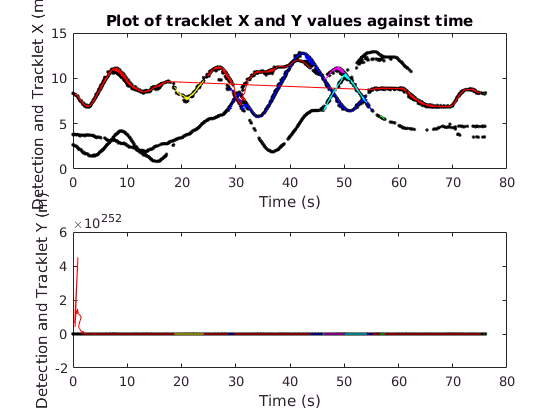

%setup the figure
hold on
colors_o = {'ro','go','bo','co','mo','yo','ro','go','bo','co','mo','yo','ro','go','bo','co','mo','yo'};
colors = {'r','g','b','c','m','y','r','g','b','c','m','y','r','g','b','c','m','y'};

for i=1:size(tracklet_table_array)
    table = tracklet_table_array{i,2}(:,:); % get the current table
    % x plot
    subplot(2,1,1)
    hold on
    plot(table.Time, table.KF_X,colors{i},'LineWidth',.2)
    
    % y plot
    subplot(2,1,2)
    hold on
    plot(table.Time, table.KF_Y,colors{i},'LineWidth',.2)
end

% figure stuff
subplot(2,1,1)
title('Plot of tracklet X and Y values against time')
xlabel('Time (s)')
ylabel('Detection and Tracklet X (m)')
% axis([0 50 0 15])

subplot(2,1,2)
xlabel('Time (s)')
ylabel('Detection and Tracklet Y (m)')
% axis([0 50 0 15])
saveas(gcf,'detections_and_tracklets_0.eps')
saveas(gcf,'detections_and_tracklets_0.png')

Now we want to plot covariance ellipses at each point



%test the PlotEllipse function stolen from PN
figure
x = [2; 4];
P = [.3 0.2;
    0.4 1];
nSigma = 8

nSigma = 8

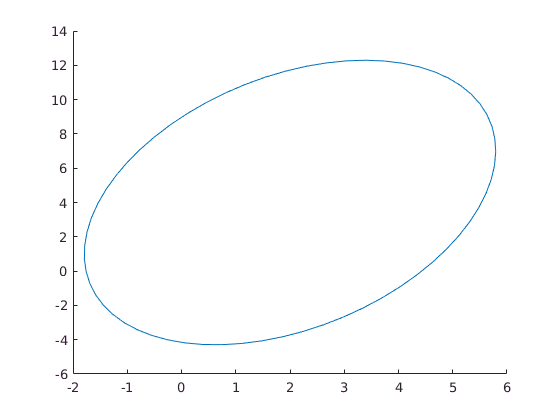

h = PlotEllipse(x,P,nSigma);


drawnow

So split into 

% every 10 results, plot 1) the estimate and 2 a covariance ellipse
figure
subplot(2,1,1)
plot(res_table.Time,res_table.Detection_X,'k.','LineWidth',1)

subplot(2,1,2)
plot(res_table.Time,res_table.Detection_Y,'k.','LineWidth',1)

for 

%setup the figure

hold on
filter_freq = 3; % remove 4 out of 5 results
nSigma = 0.05

nSigma = 0.0500

fprintf('we are looping through %d tracklets',size(tracklet_table_array,1))

we are looping through 9 tracklets

for i=1:size(tracklet_table_array)
% for i = 1:1
    table = tracklet_table_array{i,2}(:,:); % get the current table
    
    hold on
    
    PlotCovarianceEllipseFromTable(table, colors{i})
    
%     plot(table.Time, table.KF_X,colors{i},'LineWidth',.2)
%     
%     % y plot
%     subplot(2,1,2)
%     hold on
%     plot(table.Time, table.KF_Y,colors{i},'LineWidth',.2)
end

this tracklet has 790 data points

this tracklet has 10 data points

this tracklet has 481 data points

this tracklet has 126 data points

this tracklet has 51 data points

this tracklet has 97 data points

this tracklet has 295 data points

this tracklet has 6 data points

this tracklet has 6 data points

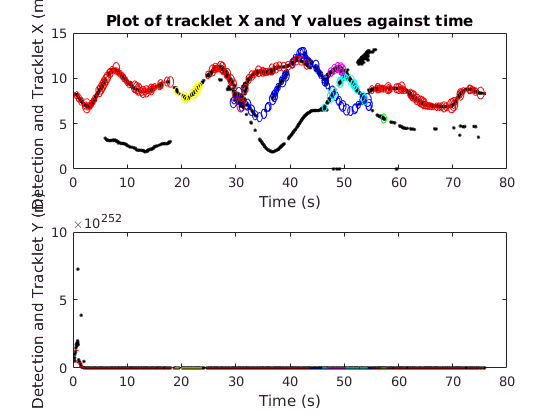


% figure stuff
subplot(2,1,1)
title('Plot of tracklet X and Y values against time')
xlabel('Time (s)')
ylabel('Detection and Tracklet X (m)')
% axis([0 50 0 15])
% 
subplot(2,1,2)
xlabel('Time (s)')
ylabel('Detection and Tracklet Y (m)')
% axis([0 50 0 15])
saveas(gcf,'detections_and_tracklets_0.eps')
saveas(gcf,'detections_and_tracklets_0.png')

wef

function PlotCovarianceEllipseFromTable(table, color)
% plots covariance ellipses of color 'color'
nSigma = 0.2;
filter_freq = 8;
% plot(table.Time, table.KF_X,color,'LineWidth',.2)
fprintf('this tracklet has %d data points',size(table,1))


for j = 1:size(table,1) % loop thru table
    if mod(j,filter_freq) == 0 % skip every result except the nth
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%X PLOTTING
        subplot(2,1,1)
        hold on
        % plot a covariance ellipse at this value
        x = [table.Time(j); table.KF_X(j)];
        P = [table.KF_cov_X(j) 0 0;
            0 table.KF_cov_Y(j) 0;
            0 0 table.KF_cov_Z(j)];
        
        h = PlotEllipse(x,P,nSigma);
        %               plot(x(1),x(2),'kx','LineWidth',.2)
        hold on
        if(~isempty(h))
            set(h,'color',color);
        end
        drawnow
        hold on
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%y PLOTTING
        subplot(2,1,2)
        hold on
        % plot a covariance ellipse at this value
        x = [table.Time(j); table.KF_Y(j)];
        P = [table.KF_cov_X(j) 0 0;
            0 table.KF_cov_Y(j) 0;
            0 0 table.KF_cov_Z(j)];
        
        h = PlotEllipse(x,P,nSigma);
        %               plot(x(1),x(2),'kx','LineWidth',.2)
        if(~isempty(h))
            set(h,'color',color);
        end
        hold on
        drawnow
        hold on
    end
end

end

function eH = PlotEllipse(x,P,nSigma)
eH = [];
P = P(1:2,1:2); % only plot x-y part
x = x(1:2);
if(~any(diag(P)==0))
    [V,D] = eig(P);
    y = nSigma*[cos(0:0.1:2*pi);sin(0:0.1:2*pi)];
    el = V*sqrtm(D)*y;
    el = [el el(:,1)]+repmat(x,1,size(el,2)+1); 
    eH = line(el(1,:),el(2,:));
end

end

fweawe

function x = mult (y)

x = 2*y
end